%导入wind
w = windmatlab;

%wind导入历史行情序列
begintime='20191102';     %时间序列开始日
endtime='20201102';       %时间序列结束日
[w_wsd_data,w_wsd_codes,w_wsd_fields,w_wsd_times,w_wsd_errorid] = w.wsd('601899.SH','close',begintime,endtime,'Priceadj=B','tradingcalendar=SSE','Days=Trading')  %获取收盘价（后复权）

w_wsd_data =     6.7529
    6.7529
    6.9864
    6.9864
    6.9864
    6.8113
    6.6945
    6.7918
    6.6945
    6.6945


w_wsd_codes = 1×1 cell 数组
    {'601899.SH'}


w_wsd_fields = 1×1 cell 数组
    {'CLOSE'}


w_wsd_times =       737733
      737734
      737735
      737736
      737737
      737740
      737741
      737742
      737743
      737744


w_wsd_errorid = 0

SA = [w_wsd_times,w_wsd_data]

SA = 	1.0e+05 *

    7.3773    0.0001
    7.3773    0.0001
    7.3773    0.0001
    7.3774    0.0001
    7.3774    0.0001
    7.3774    0.0001
    7.3774    0.0001
    7.3774    0.0001
    7.3774    0.0001
    7.3774    0.0001


clearvars -except SA w

%数据清洗
SA = rmmissing(SA);    %清除空值
time = datetime(SA(:,1),'ConvertFrom','datenum');   %将数据第一列转为datetime数组并定义为time
prices = SA(:,2);
T = timetable(time,prices);
LogReturns = diff(log(prices))

LogReturns =          0
    0.0340
         0
         0
   -0.0254
   -0.0173
    0.0144
   -0.0144
         0
         0


clearvars -except LogReturns T w

%模型模拟
%econometricModeler
md1 = garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN,'Distribution','t')

md1 =   garch - 属性:

     Description: "GARCH(1,1) Conditional Variance Model with Offset (t Distribution)"
    Distribution: Name = "t", DoF = NaN
               P: 1
               Q: 1
        Constant: NaN
           GARCH: {NaN} at lag [1]
            ARCH: {NaN} at lag [1]
          Offset: NaN

md2 = egarch('GARCHLags',1,'ARCHLags',1,'LeverageLags',1,'Offset',NaN,'Distribution','t')

md2 =   egarch - 属性:

     Description: "EGARCH(1,1) Conditional Variance Model with Offset (t Distribution)"
    Distribution: Name = "t", DoF = NaN
               P: 1
               Q: 1
        Constant: NaN
           GARCH: {NaN} at lag [1]
            ARCH: {NaN} at lag [1]
        Leverage: {NaN} at lag [1]
          Offset: NaN

GARCH = estimate(md1,LogReturns)

 
    GARCH(1,1) Conditional Variance Model with Offset (t Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    5.1716e-05      7.061e-05       0.73243         0.46391
    GARCH{1}       0.90769       0.092226         9.842      7.4189e-23
    ARCH{1}       0.048171       0.045077        1.0686         0.28523
    DoF             4.1269         1.5319         2.694       0.0070592
    Offset       0.0027065      0.0017548        1.5424         0.12298



GARCH =   garch - 属性:

     Description: "GARCH(1,1) Conditional Variance Model with Offset (t Distribution)"
    Distribution: Name = "t", DoF = 4.12687
               P: 1
               Q: 1
        Constant: 5.17164e-05
           GARCH: {0.907688} at lag [1]
            ARCH: {0.0481713} at lag [1]
          Offset: 0.00270652

EGARCH = estimate(md2,LogReturns)

 
    EGARCH(1,1) Conditional Variance Model with Offset (t Distribution):
 
                     Value      StandardError    TStatistic      PValue  
                   _________    _____________    __________    __________

    Constant        -0.14876       0.010276       -14.477      1.7047e-47
    GARCH{1}         0.97891     1.9656e-05         49802               0
    ARCH{1}         -0.22006       0.093593       -2.3512        0.018711
    Leverage{1}      0.12444       0.082671        1.5052         0.13226
    DoF                2.527        0.17981        14.054      7.2457e-45
    Offset         0.0026511     0.00037465        7.0762      1.4816e-12



EGARCH =   egarch - 属性:

     Description: "EGARCH(1,1) Conditional Variance Model with Offset (t Distribution)"
    Distribution: Name = "t", DoF = 2.52705
               P: 1
               Q: 1
        Constant: -0.148764
           GARCH: {0.978909} at lag [1]
            ARCH: {-0.220059} at lag [1]
        Leverage: {0.124438} at lag [1]
          Offset: 0.00265109

%画出10个路径上的模拟值
V0 = infer(EGARCH,LogReturns);
[V,Y] = simulate(EGARCH,252,'NumPaths',10000,'E0',LogReturns,'V0',V0)

V =     0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010
    0.0008    0.0011    0.0010    0.0011    0.0007    0.0011    0.0010    0.0010    0.0011    0.0011    0.0011    0.0009    0.0011    0.0011    0.0003    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0011    0.0010    0.0009    0.0011    0.0003    0.0010    0.0009    0.0011    0.0011    0.0011    0.0011    0.0009    0.0010    0.0011    0.0009    0.0011    0.0010    0.0010    0.0011    0.0008    0.0011    0.0011    0.0010    0.0011    0.0010    0

Y =     0.1205    0.0193   -0.0063    0.0168   -0.0461    0.0146   -0.0125    0.0308    0.0002    0.0032   -0.0032   -0.0211    0.0224    0.0059   -0.1191    0.0103   -0.0009    0.0095    0.0098    0.0064    0.0072    0.0136    0.0360    0.0387    0.0001   -0.0057   -0.0173    0.0128   -0.1206   -0.0064   -0.0176    0.0092    0.0097    0.0239    0.0245   -0.0202    0.0452    0.0123   -0.0171    0.0066   -0.0082   -0.0087    0.0059   -0.0267   -0.0021    0.0104    0.0310    0.0233   -0.0074    0.0110
    0.0041   -0.1264    0.0113   -0.0110    0.0157   -0.0152   -0.0077    0.0100   -0.0039   -0.0070    0.0129    0.0007    0.0161    0.0302    0.0100    0.0077    0.0195    0.0274    0.0327   -0.0553    0.0464   -0.0067   -0.0040    0.0119    0.0105    0.0316    0.0044   -0.0058    0.0076   -0.0084    0.0171    0.0230    0.0116   -0.0506   -0.0218   -0.0408    0.0171    0.0197    0.0179   -0.0352    0.0094    0.0107    0.0124   -0.0535    0.0228   -0.0155    0.0204   -0.0270   -0.0022    0

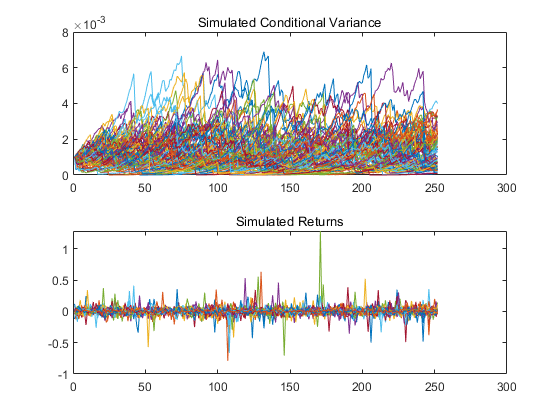

figure
subplot(2,1,1)
plot(V(:,1:100))
title('Simulated Conditional Variance')
subplot(2,1,2)
plot(Y(:,1:100))
title('Simulated Returns')

%计算预测波动率和历史波动率
tradingDays = 252;
LogReturns = rmmissing(LogReturns);
Fvol = mean(std(Y))*sqrt(tradingDays);
Hvol1Y = std(LogReturns)*sqrt(tradingDays);
disp(['Forecasted 1-year volatility = ' num2str(Fvol*100,4) '%'])

Forecasted 1-year volatility = 51.03%


disp(['Historical 1-year volatility = ' num2str(Hvol1Y*100,4) '%'])

Historical 1-year volatility = 48.21%
